clear all
clf
format shortg
% data = xlsread("Statestik\Eksamens sæt\21E\Data_M4STI1_2021E.xlsx");

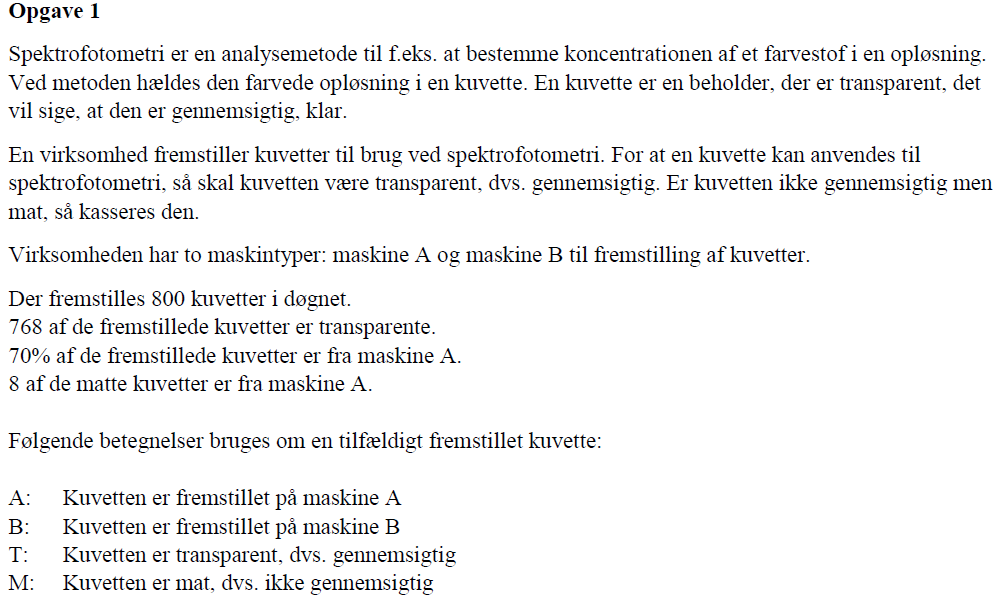

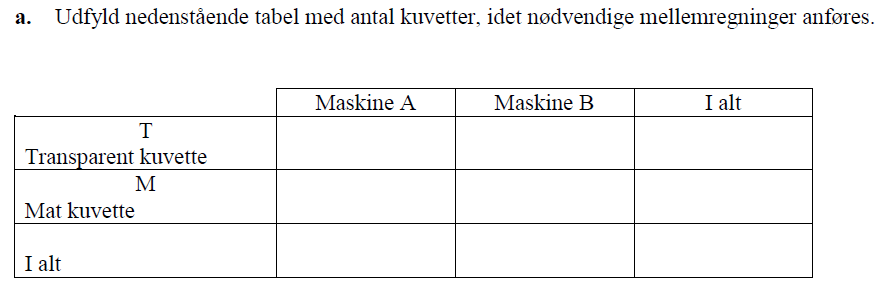

tot = 800

tot =    800


tot_T = 768

tot_T =    768


tot_M = tot - tot_T

tot_M =     32


A_tot = 0.7 * tot

A_tot =    560


A_M = 8

A_M =      8


A_T = A_tot - A_M

A_T =    552


B_tot = tot - A_tot

B_tot =    240


B_T = tot_T - A_T

B_T =    216


B_M = tot_M - A_M

B_M =     24


Kol_names = {'Maskine A', ' Maskine B', 'I alt'};
row_names = {'T - Transparent kuvette', 'M - Mat kuvette', 'I alt'};
table([A_T; A_M; A_tot], [B_T; B_M; B_tot], [tot_T; tot_M; tot], VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
                               Maskine A     Maskine B    I alt
                               _________    __________    _____

    T - Transparent kuvette       552          216         768 
    M - Mat kuvette                 8           24          32 
    I alt                         560          240         800 


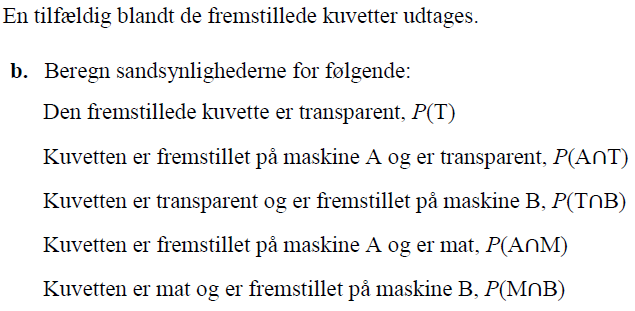

P_T = tot_T / tot

P_T =          0.96


P_A_fel_T = A_T/tot

P_A_fel_T =          0.69


P_T_fel_B = B_T/tot

P_T_fel_B =          0.27


P_A_fel_M = A_M/tot

P_A_fel_M =          0.01


P_M_fel_T = B_M/tot

P_M_fel_T =          0.03


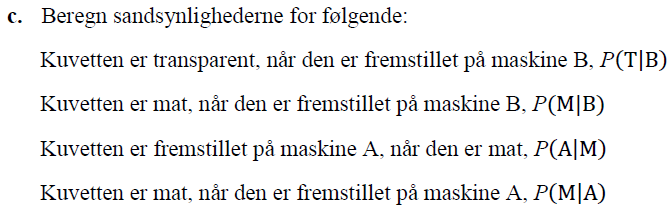

P_T_giv_B = B_T / B_tot

P_T_giv_B =           0.9


P_M_giv_B = B_M / B_tot

P_M_giv_B =           0.1


P_A_giv_M = A_M / tot_M

P_A_giv_M =          0.25


P_M_giv_A = A_M / A_tot

P_M_giv_A =      0.014286


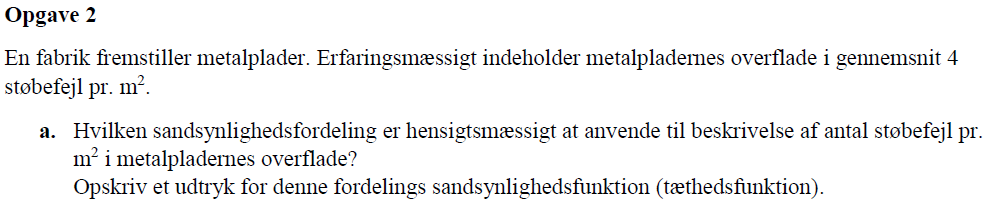

Possion fordelling vælges da den er disrket og der tælles fejl fra nul.

b. Bestem fordelingens middelværdi, varians og standardafvigelse.

lambda = 4 %middel værdi

lambda =      4


var = lambda %variansen

var =      4


std = sqrt(lambda) %standardafvigelsen

std =      2


P_3 = poisspdf(3,lambda)

P_3 =       0.19537


Sandsynligheden for 3 fejl er således 19,54%

d. Bestem sandsynligheden for at antallet af støbefejl er mindre eller lig med 6.

P_6kul = poisscdf(6,lambda)

P_6kul =       0.88933


Sandsynligheden for 6 fejl eller mindre er således 88,93%

e. Bestem sandsynligheden for at antallet af støbefejl er større eller lig med 7.

P_7kul_plus = 1 - P_6kul

P_7kul_plus =       0.11067


Sandsynligheden for 7 eller flere fejl er således 11,07%

f. Bestem sandsynligheden for at antallet af støbefejl ligger mellem 2 og 5.

P_2kul = poisscdf(2,lambda);
P_4kul = poisscdf(4,lambda);
P_25 = P_4kul - P_2kul

P_25 =       0.39073


**eller**

P_3pdf = poisspdf(3,lambda);
P_4pdf = poisspdf(4,lambda);
P_34 = P_3pdf + P_4pdf

P_34 =       0.39073


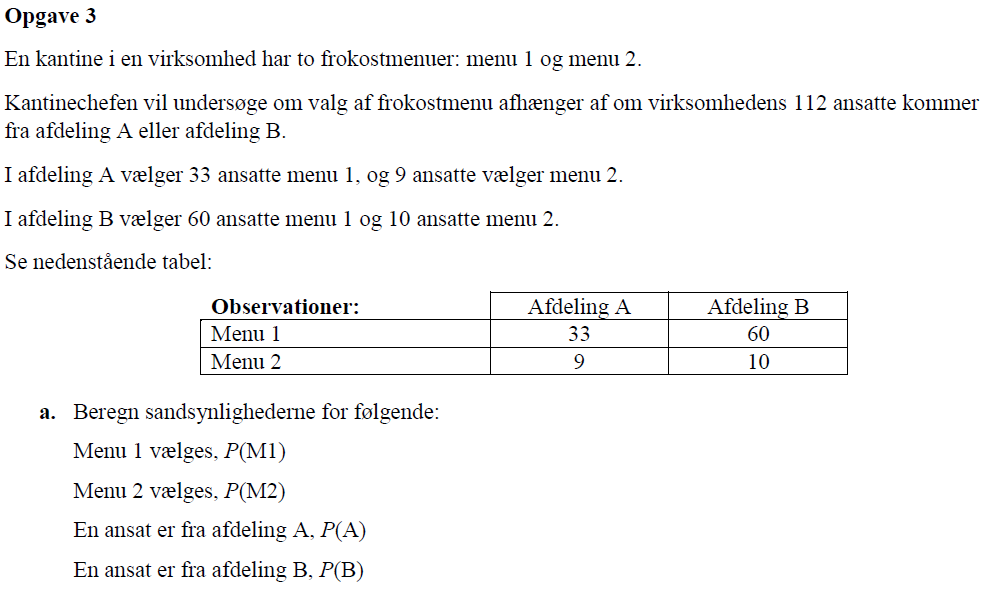

O_m1_A = 33;
O_m2_A = 9;
O_m1_B = 60;
O_m2_B = 10;

M1_tot = O_m1_A + O_m1_B

M1_tot =     93


M2_tot = O_m2_A + O_m2_B

M2_tot =     19


tot = M1_tot + M2_tot

tot =    112


P_M1 = M1_tot / tot

P_M1 =       0.83036


P_M2 = M2_tot / tot % eller 1 - P_M1

P_M2 =       0.16964


A_tot = 33 + 9

A_tot =     42


B_tot = 60 + 10

B_tot =     70


P_A = A_tot / tot

P_A =         0.375


P_B = B_tot / tot

P_B =         0.625


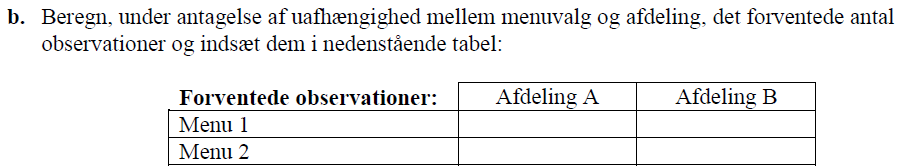

E_m1_A = tot * P_M1 * P_A

E_m1_A =        34.875


E_m1_B = tot * P_M1 * P_B

E_m1_B =        58.125


E_m2_A = tot * P_M2 * P_A

E_m2_A =         7.125


E_m2_B = tot * P_M2 * P_B

E_m2_B =        11.875



M_1 = E_m1_A + E_m1_B

M_1 =     93


M_2 = E_m2_A + E_m2_B

M_2 =     19




Kol_names = {'Afdeling A', ' Afdeling B', 'I alt'};
row_names = {'Menu 1', 'Menu 2', 'I alt'};
table(round([E_m1_A; E_m2_A; E_m1_A+ E_m2_A],0), round([E_m1_B; E_m2_B; E_m1_B + E_m2_B],0), round([M_1; M_2; tot],0), VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
              Afdeling A     Afdeling B    I alt
              __________    ___________    _____

    Menu 1        35            58           93 
    Menu 2         7            12           19 
    I alt         42            70          112 


c. Opstil nulhypotese og alternativ hypotese for hypotesetesten.

$H_0:$ valg af menu er uafhængig af afdeling

$H_a:$ valg af menu er afhængig af afdeling

d. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.

Da der testes for uafhængighed benyttes en Chi i anden test:

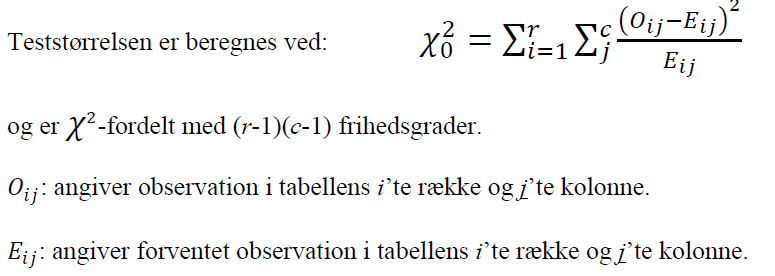

e. Bestem den kritiske værdi og angiv det kritiske område for testen, når der vælges et signifikansniveau på 5%.

alpha = 1 - 0.05

alpha =          0.95


df = (2 - 1) * (2 - 1) % en to gange to matrix estameres 

df =      1


chi2inv(alpha, df)

ans =        3.8415


Vi forskater $H_0$ hvis $\chi^2 > 3,8415$ 

f. Beregn teststørrelses (teststatistikkens) værdi. Mellemregninger skal fremgå.

chi2_M1_A = (O_m1_A - E_m1_A)^2 / E_m1_A

chi2_M1_A =       0.10081


chi2_M2_A = (O_m2_A - E_m2_A)^2 / E_m2_A

chi2_M2_A =       0.49342


chi2_M1_B = (O_m1_B - E_m1_B)^2 / E_m1_B

chi2_M1_B =      0.060484


chi2_M2_B = (O_m2_B - E_m2_B)^2 / E_m2_B

chi2_M2_B =       0.29605


chi2_test = chi2_M1_A + chi2_M2_A + chi2_M1_B + chi2_M2_B

chi2_test =       0.95076


g. Konkluder på hypotesetesten.

Det ses at $1,088 < 3,8415$ og vi er kan således ikke forkaste vores $H_0$.

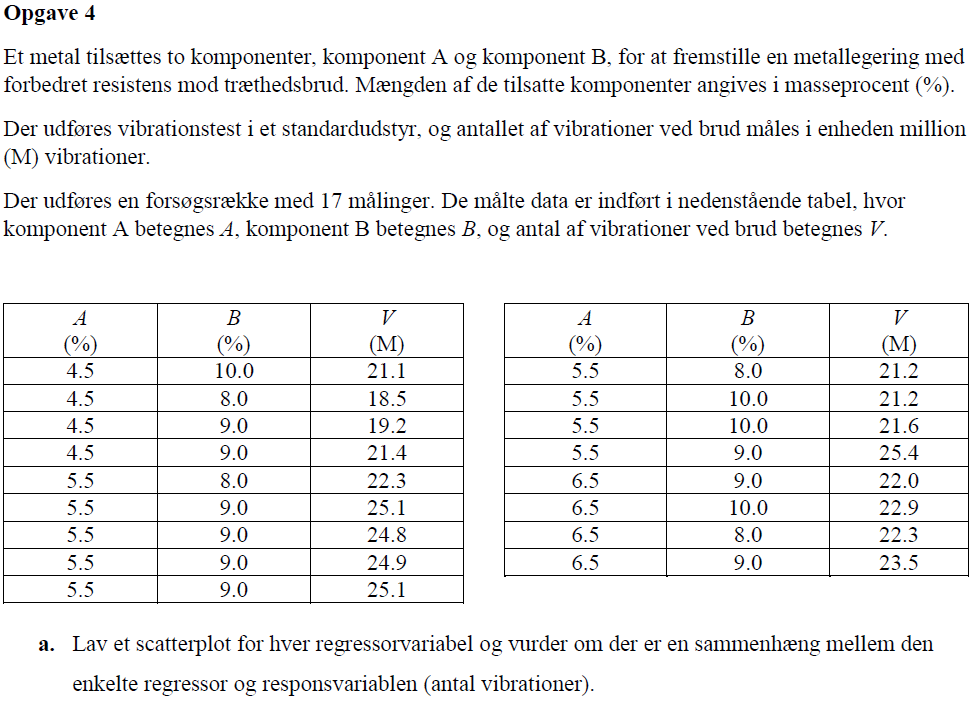

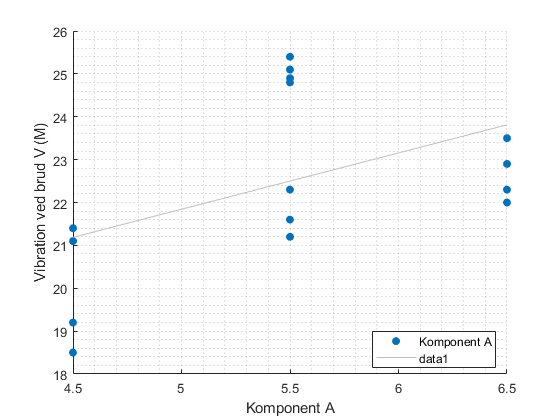

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\21E\Data_M4STI1_2021E.xlsx", 'G:I');
A = data(:,1);
B = data(:,2);
V = data(:,3);

figure(1)
scatter(A, V, 'filled', DisplayName='Komponent A')
lsline
xlabel('Komponent A')
ylabel('Vibration ved brud V (M)')
grid('minor')
legend('Location','best')

Der ses en linær positiv sammenhæng med komponent A, dog med lidt spredte data.

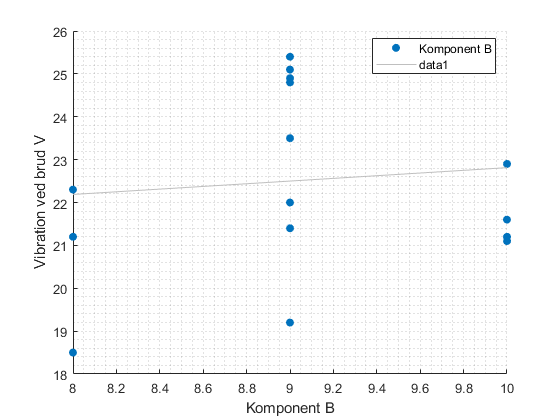


figure(2)
scatter(B, V, 'filled', DisplayName='Komponent B')
lsline
xlabel('Komponent B')
ylabel('Vibration ved brud V')
grid('minor')
legend('Location','best')

Der ses en linær positiv sammenhæng med komponent B, dog med lidt spredte data og i mindre grad end ved A.

b. Lav en multipel lineær regressionsanalyse, der beskriver antallet af vibrationer som funktion af tilsat mængde af komponent A og af komponent B. Opskriv regressionsligningen.

mdl1 = fitlm([A, B], V) %, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2') % til en anderledes model

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    _______    ______    ________

    (Intercept)     12.469        7.35    1.6964     0.11192
    x1              1.3125     0.69538    1.8875    0.080004
    x2              0.3125     0.69538    0.4494     0.66002


Number of observations: 17, Error degrees of freedom: 14
Root Mean Squared Error: 1.97
R-squared: 0.212,  Adjusted R-Squared: 0.0993
F-statistic vs. constant model: 1.88, p-value = 0.189


$$V(A,B) = 12,469 + 1,3125 \cdot A + 0,3125 \cdot B$$


c. Vurder ud fra regressionsanalysens statistikker (f.eks. 𝑅2,𝐹 og p-værdi) om modellen beskriver observationerne godt. Anvend et signifikansniveau, 𝛼=0.05 ved din vurdering.

Nej R værdi og høje P værdier

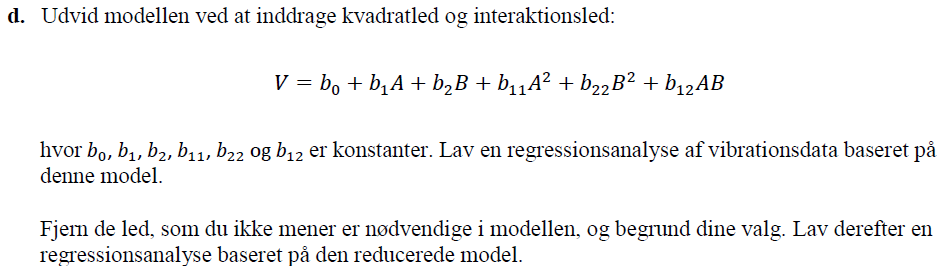

mdl2 = fitlm([A, B], V, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2') % til en anderledes model

mdl2 = Linear regression model:
    y ~ 1 + x1*x2 + x1^2 + x2^2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -233.08      59.593    -3.9112    0.0024292
    x1              28.232      8.6834     3.2513    0.0077177
    x2              38.849      11.394     3.4096    0.0058295
    x1:x2             -0.5     0.62004    -0.8064       0.4371
    x1^2           -2.0382      0.6035    -3.3772    0.0061728
    x2^2           -1.9882      0.6035    -3.2944     0.007149


Number of observations: 17, Error degrees of freedom: 11
Root Mean Squared Error: 1.24
R-squared: 0.754,  Adjusted R-Squared: 0.642
F-statistic vs. constant model: 6.

mdl2 = fitlm([A, B], V, 'y ~ x1 + x2 + x1^2 + x2^2') % til en anderledes model

mdl2 = Linear regression model:
    y ~ 1 + x1 + x2 + x1^2 + x2^2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -208.33      50.332    -4.1392    0.0013729
    x1              23.732      6.5553     3.6203    0.0035126
    x2              36.099      10.712     3.3699    0.0055711
    x1^2           -2.0382     0.59464    -3.4275    0.0050083
    x2^2           -1.9882     0.59464    -3.3435    0.0058506


Number of observations: 17, Error degrees of freedom: 12
Root Mean Squared Error: 1.22
R-squared: 0.739,  Adjusted R-Squared: 0.652
F-statistic vs. constant model: 8.51, p-value = 0.00171

e. Opskriv ligningen for din foretrukne model.


$$V(A,B) = -208,33 + 23,732 \cdot A + 36,099 \cdot B - 2,0382 \cdot A^2 - 1,9882 \cdot B^2$$


f. Undersøg om der er ”unormale” datapunkter, dvs. løftestangspunkter, outliers, indflydelsespunkter. Svaret skal begrundes.

lev = mdl2.Diagnostics.Leverage; %løfte punkter %'unormale' i x-retningen
rst = mdl2.Residuals.Studentized; % Outlier punkter "unormale" værdier i y-retningen. abs(rst) skal gerne være mindre end 3


c = 4; %antal regressor variable
n = length(rst); %antalt observationer
lev_limit = 2 * (c +1 )/ n

lev_limit =       0.58824


find(lev > lev_limit)


ans =

  0×1 empty double column vector



find(abs(rst) > 3)


ans =

  0×1 empty double column vector



nr = (1:length(rst))'; 
disp(table(nr, A, B, V, lev, rst))

    nr     A     B      V        lev        rst   
    __    ___    __    ____    _______    ________

     1    4.5    10    21.1    0.43421      2.1495
     2    4.5     8    18.5    0.43421    -0.25432
     3    4.5     9    19.2    0.30921     -2.0415
     4    4.5     9    21.4    0.30921     0.33728
     5    5.5     8    22.3    0.30921     0.19447
     6    5.5     9    25.1    0.15789     0.61239
     7    5.5     9    24.8    0.15789     0.34795
     8    5.5     9    24.9    0.15789     0.43513
     9    5.5     9    25.1    0.15789     0.61239
    10    5.5     8    21.2    0.30921    -0.87153
    11    5.5    10    21.2    0.30921     -1.5878
    12    5.5    10    21.6    0.30921     -1.1128
    13    5.5     9    25.4    0.15789     0.88865
    14    6.5     9      22   

g. Lav et box-plot, et histogram og et normalfordelingsplot for de studentiserede residualer. Kommenter de tre plots.

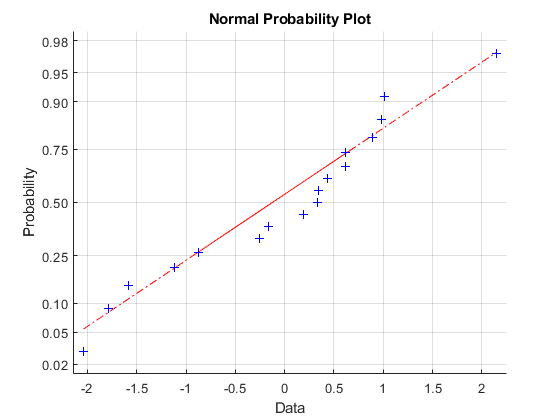

normplot(rst)